%% Biosignal Processing - Lab 1 Part 2
%% AR-model estimation

clear; close all; clc;

%% Task 2.1 - Load data
data = load('ar_data.mat');
y = data.y;

N = length(y);


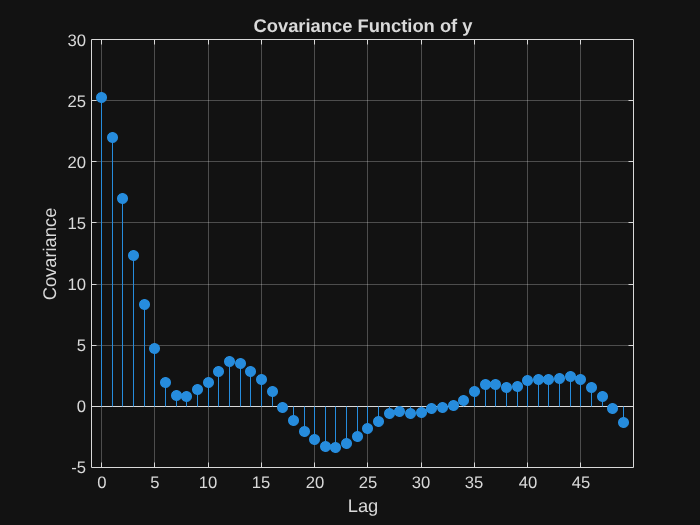

%% Task 2.2 - Covariance function
covariance = covf(y,50);

figure;
stem(0:49, covariance, 'filled');
xlabel('Lag');
ylabel('Covariance');
title('Covariance Function of y');
grid on;

%% Task 2.3 - Fit AR(p) models 
max_p = 20;

ar_models = cell(max_p,1);      % Store each model
ar_coefficients = cell(max_p,1); % Store coefficients

for p = 1:max_p

    % Fit AR(p) model
    ar_models{p} = arx(iddata(y), p);

    % Get AR polynomial coefficients
    ar_coefficients{p} = ar_models{p}.A;

end

% Display some coefficients as an example
for p = 1:5
    fprintf('AR(%d) coefficients:\n', p);
    disp(ar_coefficients{p});
end

AR(1) coefficients:


    1.0000   -0.8816



AR(2) coefficients:


    1.0000   -1.1997    0.3650



AR(3) coefficients:


    1.0000   -1.1995    0.3634    0.0012



AR(4) coefficients:


    1.0000   -1.1992    0.3876   -0.0827    0.0706



AR(5) coefficients:


    1.0000   -1.1937    0.3804   -0.0507   -0.0279    0.0829



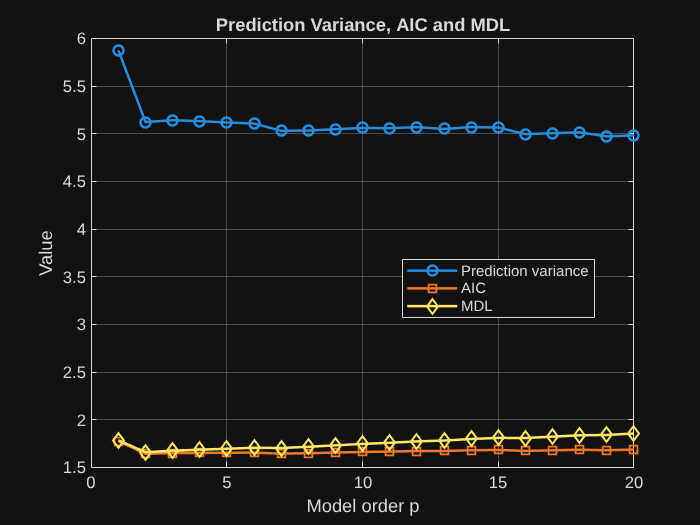

%% Task 2.4 - Prediction error variance, AIC and MDL
variance = zeros(max_p,1);
AIC = zeros(max_p,1);
MDL = zeros(max_p,1);

for p = 1:max_p

    % Variance of the prediction error
    variance(p) = ar_models{p}.NoiseVariance;

    % Akaike Information Criterion
    AIC(p) = log(variance(p)) + (2*p)/N;

    % Minimum Description Length
    MDL(p) = log(variance(p)) + (p*log(N))/N;

end

%% Plot prediction variance, AIC and MDL
figure;

plot(1:max_p, variance, 'o-', 'LineWidth', 1.5);
hold on;
plot(1:max_p, AIC, 's-', 'LineWidth', 1.5);
plot(1:max_p, MDL, 'd-', 'LineWidth', 1.5);

xlabel('Model order p');
ylabel('Value');
title('Prediction Variance, AIC and MDL');
legend('Prediction variance', 'AIC', 'MDL', 'Location', 'best');
grid on;

%% Task 2.5 - Optimal model order
min_MDL = min(MDL);
min_AIC = min(AIC);

p0_MDL = find(MDL == min_MDL);
p0_AIC = find(AIC == min_AIC);

fprintf('MDL chooses p = %d\n', p0_MDL);

MDL chooses p = 2


fprintf('AIC chooses p = %d\n', p0_AIC);

AIC chooses p = 2


%% Task 2.6 - Fit the optimal AR model
p0 = p0_MDL;                     

ar_model0 = arx(iddata(y), p0);

% Display coefficients and confidence intervals
present(ar_model0)


ar_model0 =
Discrete-time AR model: A(z)y(t) = e(t)                      
  A(z) = 1 - 1.2 (+/- 0.04195) z^-1 + 0.365 (+/- 0.0421) z^-2
                                                             
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=2
   Number of free coefficients: 2
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data.         
Fit to estimation data: 55.08% (prediction focus)
FPE: 5.164, MSE: 5.082                           
More information in model's "Report" property.
 
Model Properties


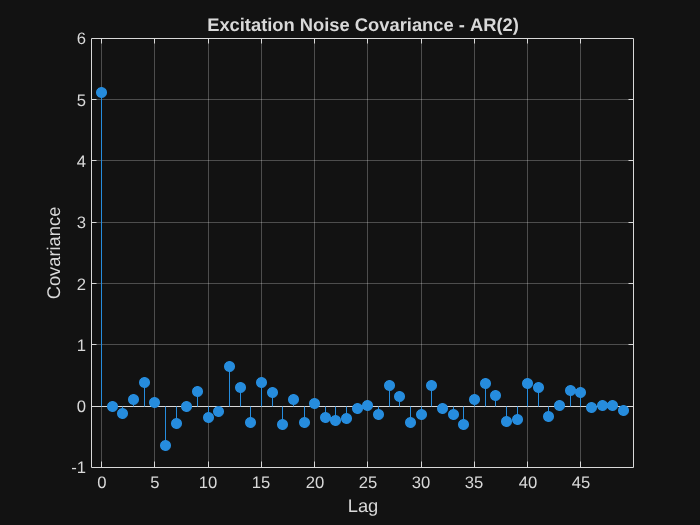


%% Estimate the excitation noise
noise = filter(ar_model0.A, 1, y);

%% Covariance function of the excitation noise
covariance_noise = covf(noise, 50);

figure;
stem(0:49, covariance_noise, 'filled');
xlabel('Lag');
ylabel('Covariance');
title(sprintf('Excitation Noise Covariance - AR(%d)', p0));
grid on;

%% Task 2.7 - Fit a "too large" model (AR(p0 + 1))
ar_model_large = arx(iddata(y), p0 + 1);

% Display coefficients and confidence intervals
present(ar_model_large)


ar_model_large =
Discrete-time AR model: A(z)y(t) = e(t)                                                       
  A(z) = 1 - 1.199 (+/- 0.04507) z^-1 + 0.3634 (+/- 0.0684) z^-2 + 0.001226 (+/- 0.04527) z^-3
                                                                                              
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=3
   Number of free coefficients: 3
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data.         
Fit to estimation data: 55.09% (prediction focus)
FPE: 5.203, MSE: 5.08                            
More information in model's "Report" property.
 


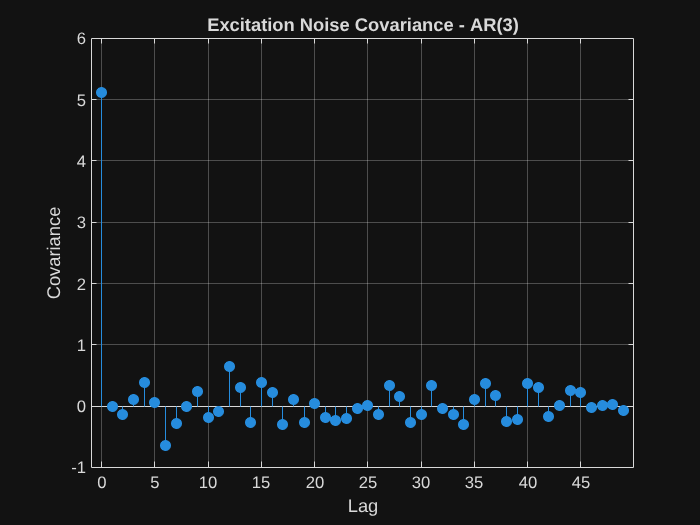


% Estimate the excitation noise
noise_large = filter(ar_model_large.A, 1, y);

% Covariance function of the excitation noise
covariance_large = covf(noise_large, 50);

figure;
stem(0:49, covariance_large, 'filled');
xlabel('Lag');
ylabel('Covariance');
title(sprintf('Excitation Noise Covariance - AR(%d)', p0 + 1));
grid on;

%% Task 2.8 - Fit a "too small" model (AR(p0 - 1))

ar_model_small = arx(iddata(y), p0 - 1);

% Display coefficients and confidence intervals
present(ar_model_small)


ar_model_small =
Discrete-time AR model: A(z)y(t) = e(t)
  A(z) = 1 - 0.8816 (+/- 0.02172) z^-1 
                                       
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=1
   Number of free coefficients: 1
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                         
Estimated using ARX on time domain data.        
Fit to estimation data: 51.8% (prediction focus)
FPE: 5.9, MSE: 5.853                            
More information in model's "Report" property.
 
Model Properties


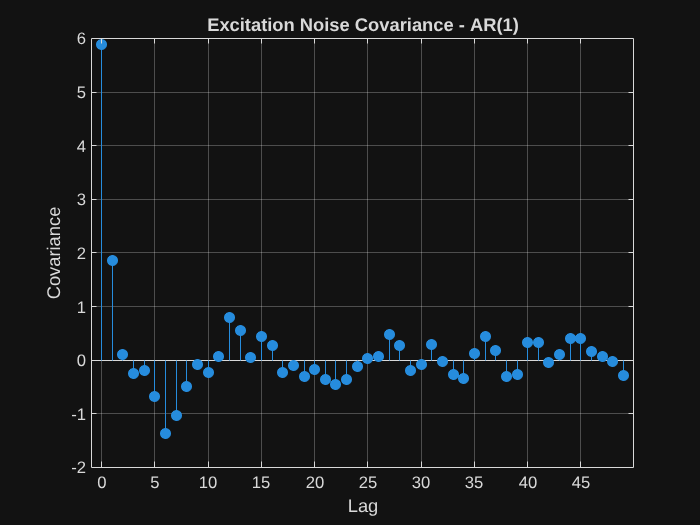


% Estimate the excitation noise
noise_small = filter(ar_model_small.A, 1, y);

% Covariance function of the excitation noise
covariance_small = covf(noise_small, 50);

figure;
stem(0:49, covariance_small, 'filled');
xlabel('Lag');
ylabel('Covariance');
title(sprintf('Excitation Noise Covariance - AR(%d)', p0 - 1));
grid on;

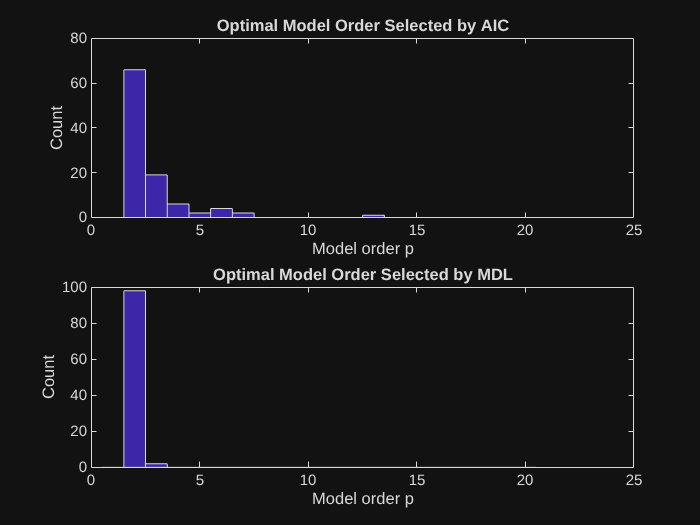

%% Task 2.10 - Simulation study
N_sim = 500;
num_simulations = 100;

AIC_order = zeros(num_simulations,1);
MDL_order = zeros(num_simulations,1);

for i = 1:num_simulations

    % Simulate N = 500 samples from the optimal AR(p0) model
    w = randn(N_sim,1);
    y_sim = filter(1, ar_model0.A, w);

    AIC_sim = zeros(max_p,1);
    MDL_sim = zeros(max_p,1);

    % Fit AR models of order 1 to 20
    for p = 1:max_p

        ar_model = arx(iddata(y_sim), p);

        prediction_variance = ar_model.NoiseVariance;

        % Compute AIC and MDL
        AIC_sim(p) = log(prediction_variance) + (2*p)/N_sim;
        MDL_sim(p) = log(prediction_variance) + (p*log(N_sim))/N_sim;

    end

    % Save optimal model order
    AIC_order(i) = find(AIC_sim == min(AIC_sim), 1);
    MDL_order(i) = find(MDL_sim == min(MDL_sim), 1);

end

%% Histograms of selected model orders
figure;

subplot(2,1,1)
hist(AIC_order, 1:max_p)
xlabel('Model order p')
ylabel('Count')
title('Optimal Model Order Selected by AIC')

subplot(2,1,2)
hist(MDL_order, 1:max_p)
xlabel('Model order p')
ylabel('Count')
title('Optimal Model Order Selected by MDL')


%% Display results
AIC_correct = sum(AIC_order == p0);
MDL_correct = sum(MDL_order == p0);

fprintf('AIC selected p0 = %d in %d out of %d simulations.\n', ...
    p0, AIC_correct, num_simulations);

AIC selected p0 = 2 in 66 out of 100 simulations.



fprintf('MDL selected p0 = %d in %d out of %d simulations.\n', ...
    p0, MDL_correct, num_simulations);

MDL selected p0 = 2 in 98 out of 100 simulations.
